# **UNIVERSIDAD AUTONOMA CHAPINGO  **

# **DEPARTAMENTO DE INGENIERIA MECANICA AGRICOLA  **

# **CURSO INGENIERIA DE CONTROL MODERNO  **

# **TAREA NO. 3 ** 

### Cano García Eduardo

### 6° 6

El modelo de una aeronave esta dado por la función de transferencia: 


$$G\left(s\right)=\frac{1\ldotp 151s+0\ldotp 1774}{s^3 +0\ldotp 739s^2 +0\ldotp 921s}$$


Se desea diseñar un sistema de control que cuando se le aplique una entrada escalón de magnitud 0.2 radianes, en lazo cerrado tenga el comportamiento siguiente:  

a)  Sobre impulso (overshoot) menor del 10%  

b) Tiempo de subida (rise time) menor de 2 segundos  

c) Tiempo de asentamiento (settling time) menor de 10 segundos  

d) Error en estado estacionario (steady-state error) menor de 2% 

**Problema 1. Diseñar un controlador con adelanto mediante el método de diseño de  respuesta en frecuencia. Sugerencia: usar la herramienta controlSystemDesigner de  MATLAB. **

K=110

K = 110

num= K*[1.151 0.1774]

num =   126.6100   19.5140


den= [1 0.739 0.921 0]

den =     1.0000    0.7390    0.9210         0


Gs=tf(num,den)


Gs =
 
       126.6 s + 19.51
  -------------------------
  s^3 + 0.739 s^2 + 0.921 s
 
Continuous-time transfer function.


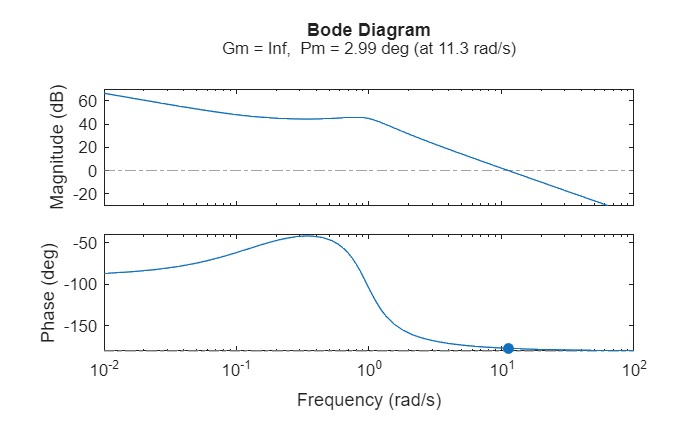

margin(Gs)

Gscl=feedback(Gs,1)


Gscl =
 
           126.6 s + 19.51
  ---------------------------------
  s^3 + 0.739 s^2 + 127.5 s + 19.51
 
Continuous-time transfer function.


Numc =[1  1.5]

Numc =     1.0000    1.5000


DenC=[1 18.1]

DenC =     1.0000   18.1000


NumCompensado=conv(num,Numc)

NumCompensado =   126.6100  209.4290   29.2710


DenCompensado=conv(den,DenC)

DenCompensado =     1.0000   18.8390   14.2969   16.6701         0


SysCompensado=tf(NumCompensado,DenCompensado)


SysCompensado =
 
      126.6 s^2 + 209.4 s + 29.27
  ------------------------------------
  s^4 + 18.84 s^3 + 14.3 s^2 + 16.67 s
 
Continuous-time transfer function.


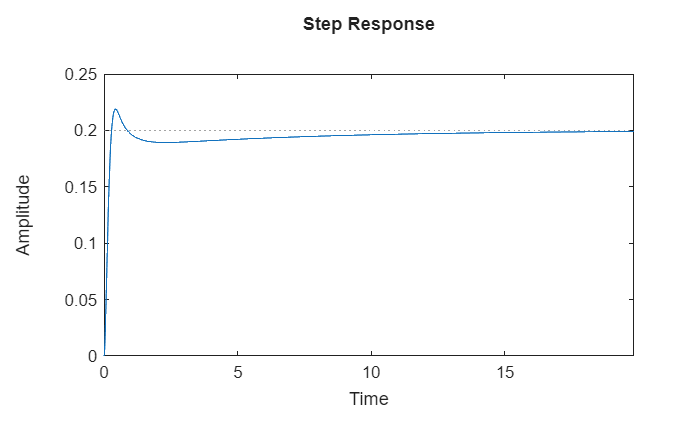

SysCompenscl = feedback(SysCompensado, 1);
step(0.2*SysCompenscl);

stepinfo(0.2*SysCompenscl)

ans = struct with fields:
         RiseTime: 0.1906
    TransientTime: 9.7975
     SettlingTime: 9.7975
      SettlingMin: 0.1832
      SettlingMax: 0.2188
        Overshoot: 9.4117
       Undershoot: 0
             Peak: 0.2188
         PeakTime: 0.4292


Tenemos un `Overshoot: 9.4117 s`e cumplio un sobre impulso (overshoot) menor del 10%  

Tenemos un `RiseTime: 0.1906 se cumplio un t`iempo de subida (rise time) menor de 2 segundos  

Tenemos un `SettlingTime: 9.7975` se cumplio un tiempo de asentamiento (settling time) menor de 10 segundos  

Error en estado estacionario (steady-state error) menor de 2% 

**Problema 2. Obtener el modelo en la representación de Espacio de Estados del  modelo de la aeronave analíticamente. Nota: pueden complicarse las soluciones de los  problemas 4, 6 y 8 si se usa la función [A,B,C,D]=tf2ss(num, den) de MATLAB.**

num= [1.151 0.1774]

num =     1.1510    0.1774


den= [1 0.739 0.921 0]

den =     1.0000    0.7390    0.9210         0


[A,B,C,D]=tf2ss(num, den);
% Display the state-space matrices
disp('State-space matrices:');

State-space matrices:


disp('A = '), disp(A);

A = 
   -0.7390   -0.9210         0
    1.0000         0         0
         0    1.0000         0



disp('B = '), disp(B);

B = 
     1
     0
     0



disp('C = '), disp(C);

C = 
         0    1.1510    0.1774



disp('D = '), disp(D);

D = 
     0



**Problema 3. Verificar si el sistema es completamente controlable.**

% Aplicar la prueba de controlabilidad
controllabilityMatrix = ctrb(A, B);
disp('Matriz de Controlabilidad: '), disp(controllabilityMatrix);

Matriz de Controlabilidad: 
    1.0000   -0.7390   -0.3749
         0    1.0000   -0.7390
         0         0    1.0000



determMatrixControl = det(controllabilityMatrix)

determMatrixControl = 1

% Rango de la matriz de Contrabilidad
rankControl = rank(controllabilityMatrix)

rankControl = 3

El orden del sistema es el mismo que la matriz de controlabilidad y su determinante es 1 lo que significa que el sistema es completamente controlable.

**Problema 4. Diseñar un controlador mediante el método de colocación de polos.**

kA_5 = [4.0610    2.7295    1.8021]

kA_5 =     4.0610    2.7295    1.8021


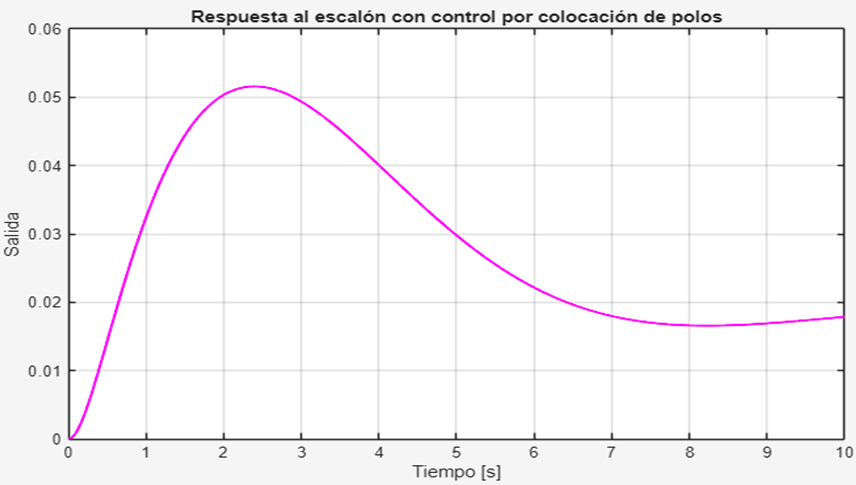

**Problema 5. Verificar si el sistema es completamente observable.**

% Aplicar la prueba de observavilidad
sys = ss(A,B,C,D);
observabilityMatrix = obsv(A,C);
disp('Matriz de Observabilidad para el sistema: '), disp(observabilityMatrix);

Matriz de Observabilidad para el sistema: 
         0    1.1510    0.1774
    1.1510    0.1774         0
   -0.6732   -1.0601         0



rank(observabilityMatrix)

ans = 3

rank(obsv(sys))

ans = 3

order(sys)

ans = 3

El orden y rango del sistema es el mismo que la matriz de observabilidad lo que significa que el sistema es observable.

**Problema 6. Diseñar un controlador-observador que use un observador de estados de  orden completo y la matriz de ganancias de retroalimentación de los estados (K)  obtenida en el Problema 4. **

L = [130.0174; -104.5150; 921.9714]

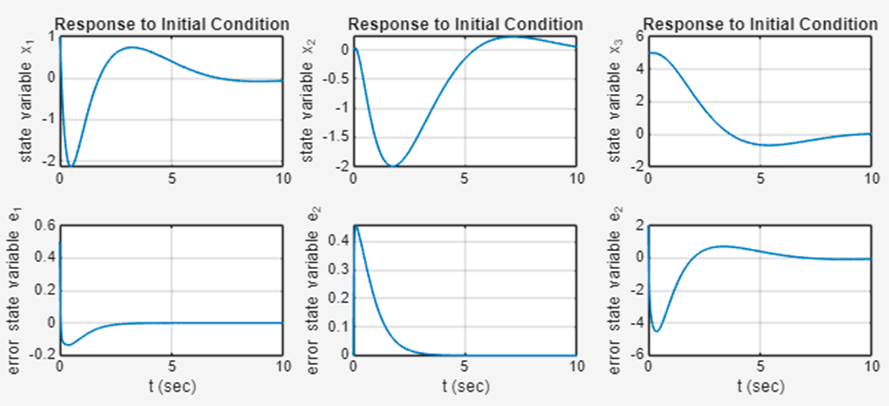

Como se muestra en la simulación, el observador funciona porque todas las variables llegan a cero

**Problema 7. Diseñar un controlador mediante el método del regulador lineal  cuadrático (Linear Quadratic Regulator: LQR). Comentario: para este problema ver el  ejemplo controladorobservadorordcompletoLQR.mlx**

% LQR
Q = C'*C;     % Penaliza la salida
R = 1;        % Penaliza el esfuerzo de control
K = lqr(A,B,Q,R)

K =     0.6656    0.7134    0.1774


**Problema 8. Diseñar un controlador-observador que use un observador de estados de  orden completo y la matriz de ganancias de retroalimentación de los estados (K)  obtenida en el Problema 7. Comentario: para este problema ver el ejemplo  controladorobservadorordcompletoLQR.mlx **

% Observador: ubicamos polos del observador 5 veces a la izquierda
desired_observer_poles = 5 * real(eig(A - B*K));
L = acker(A', C', desired_observer_poles)'  % Transpuesto por convención

L =     7.3224
    0.9747
   29.0999


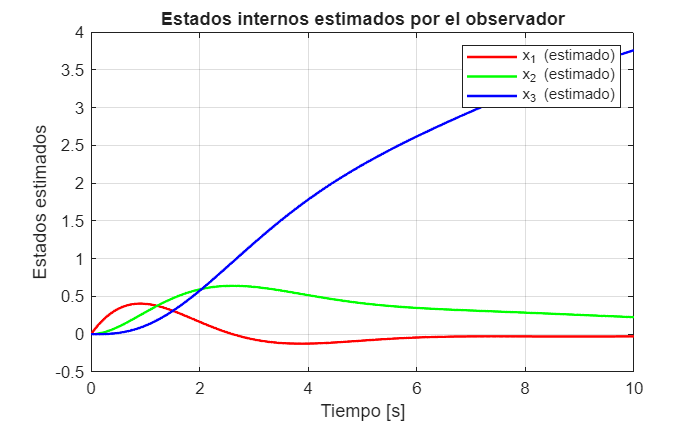


% Sistema extendido: estados + estimador (orden 2n)
A_est = [(A - B*K)        B*K;
         zeros(size(A))   (A - L*C)];

B_est = [B; zeros(size(B))];
C_est = [C, zeros(size(C))];
D_est = D;

% Sistema en espacio de estados con observador + LQR
sys_obs_lqr = ss(A_est, B_est, C_est, D_est);

% Simulación
t = 0:0.01:10;
[y,t,x] = step(0.2 * sys_obs_lqr, t);  % Entrada escalón de 0.2 rad

figure;
plot(t, x(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'g', 'LineWidth', 1.5);
plot(t, x(:,3), 'b', 'LineWidth', 1.5);
legend('x_1 (estimado)', 'x_2 (estimado)', 'x_3 (estimado)')
xlabel('Tiempo [s]')
ylabel('Estados estimados')
title('Estados internos estimados por el observador')
grid on;

**Problema 9.  Comparar gráficamente, el comportamiento de los sistemas de control  obtenidos en el Problema 1 y en el Problema 4. **

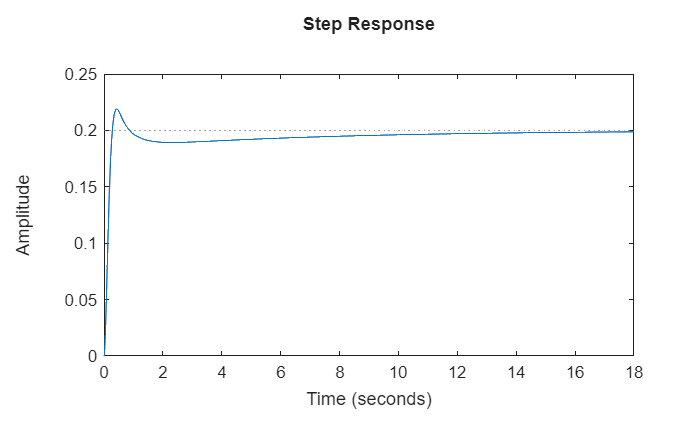

El controlador que emplea una matriz de retroalimentación no logra alcanzar el estado deseado de forma efectiva. Por otro lado, el controlador de adelanto, diseñado con base en la respuesta en frecuencia, demuestra una mayor eficacia. Sin embargo, este último tiene una desventaja crucial: su polo está ubicado a una distancia considerable del origen, lo que podría hacerlo impráctico en un escenario real.

**Problema 10. Comparar gráficamente, el comportamiento de los sistemas de control  obtenidos en el Problema 1 y en el Problema 7.**

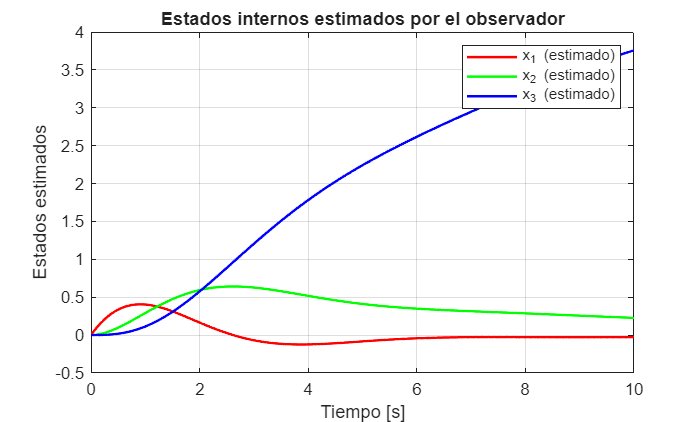

Observamos que la salida (indicada en rojo) está mucho más estable que en el problema 4. La sobre elongación, si bien está muy cerca del límite, aún cumple con los requisitos de diseño. Notablemente, la transición es menos abrupta que la del problema 1. Esto se debe al esfuerzo de control aplicado por las matrices, que permite esta transición suave mientras el sistema se aproxima al estado estacionario. Aunque toma un poco más de tiempo, el sistema permanece dentro de los parámetros deseados.